# Nonlocal Cahn–Hilliard with source

Here we will test the Multi Shape-based Singular Kernel that we have obtained so far to solve an NCH system with a source. The source is such that we should be able to, at least numerically, consider its generator as an exact solution. We will provide more insights on this later on.

## Initialisation

First we define the spectral box for spatial discretisation and a spectral line for time evaluation. The spectral box will be loaded from the pre assembled Singular Kernel dataset.

% Load a SK: 10 × 10 box with 𝜀 = 10^-2
load('Singular_Kernels_Subs_10_epsA.mat', 'Newtonians')
Newtonians

Newtonians = struct with fields:
        I: @Conv_I
        J: @Conv_J
        G: @Conv_G
       NJ: [100×1 double]
       NG: [100×1 double]
       NI: [100×1 double]
      eps: 0.0100
      box: [1×1 Box]
        N: [2×1 double]
    Level: [1×1 struct]



% Retrieve box and number of collocation points
aBox     = Newtonians.box;          % This is the domain
[N1, N2] = deal(aBox.N1, aBox.N2);
epsilon  = Newtonians.eps;          % This is ε

For the selected box and value of $\varepsilon ,$ we select a convolution matrix based on a subdivision factor:

Newtonians.Level.Available          % Check available matrices

ans =      2    10    16


% Select convolution matrix
Conv = Newtonians.Level.n16;         % Name format: 'n' + factor
% Retrieve additional data
Conv_D = Newtonians.NG;

Define additional structures in the box for defining the differential equation:

% Points, differentiation matrices, integration vector, and indices
% giving masks for the boundary
[Pts,Diff,Int,Ind] = aBox.ComputeAll();    
grad  = Diff.grad;       div = Diff.div;
bound = Ind.bound;    normal = Ind.normal;
Lap_Space = Diff.Lap;

% compute the interpolation matrix from the box points to a uniform
% grid [only for plotting]
Interp = aBox.ComputeInterpolationMatrix(...
                             (-1:0.02:1)',(-1:0.02:1)',true,true);

## Exact solution

Now we perform the following construction: Let $\tilde{\varphi} \left(\hat{x} ;t\right)=e^{-t} \;\sin \;\left(\hat{x_1 } \right)\;\cos \left(\hat{x_2 } \right)$, $\tilde{\mu} =F^{\prime } \left(\tilde{\varphi} \right)-K\ast \tilde{\varphi}$, $\tilde{g} \left(\hat{x} \right)=\partial_t \tilde{\varphi} \left(\hat{x} \right)-\Delta_{\hat{x} } \tilde{\mu} \left(\hat{x} \right)$. Here the function $F$ is given by $F\left(s\right)=\left(1+s\right)\;\log \left(1+s\right)+\left(1-s\right)\;\log \left(1-s\right)$ and $F^{\prime } \left(s\right)=\log \left(1+s\right)-\log \left(1-s\right)$. The hat decorator in the space variable indicates the change of variable $\hat{x} \mapsto 2\pi x$.

As such, we get that $\tilde{\varphi} \left(x;t\right)=e^{-t} \;\sin \;\left(2\pi x_1 \right)\;\cos \left(2\pi x_2 \right)$, and $\tilde{g} \left(x\right)=\partial_t \tilde{\varphi} \left(x\right)-{\left(2\pi \right)}^{-2} \Delta_x \tilde{\mu} \left(x\right)$. It is important to define everything in the ${\left\lbrack 0,1\right\rbrack }^2$ box due to the fact that the convolution matrices are defined in that domain.

First, let's define the initial condition $\rho_0 \left(x\right)=\sin \left(2\pi x\right)\;\cos \left(2\pi y\right)$:

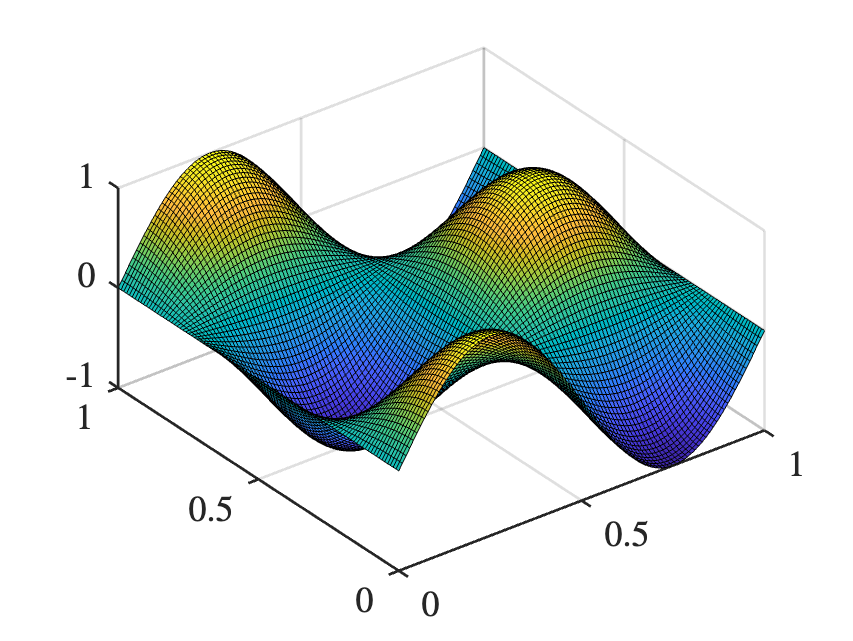

phi_ic = sin( 2.0 * Pts.y1_kv * pi ) .* cos( 2.0 * Pts.y2_kv * pi );
aBox.plot(phi_ic, {});
xlabel(''); ylabel(''); zlabel('');

Now let's compute a discretised version of $\tilde{\varphi} \left(x\right)$, for this we also discretise the interval $\left\lbrack 0,T_{\max } \right\rbrack$ but instead of starting at $0$, we start at a value $0<\varepsilon_{\textrm{Time}} \ll 1$ so that we can properly define $F^{\prime } \left(\tilde{\varphi} \right)$ everywhere:

% Time collocation points
tMax = 1.0; % Usually T = 50
n_t  = 70;   % often 100
% Set up a time line where we are currently at 
ge.yMin  = 1e-15;    ge.yMax = tMax;    ge.N = n_t;
TimeLine = SpectralLine(ge);
outTimes = TimeLine.Pts.y;
TimeLine.ComputeDifferentiationMatrix;
D_Time = TimeLine.Diff.Dy;

% Now combine
phi = exp(-outTimes) * phi_ic';

Here we can compute the derivative in time of $\tilde{\varphi} \left(x\right)$:

g_tilde = -phi;

Let's visualise $F\left(s\right)$ and its first two derivatives:

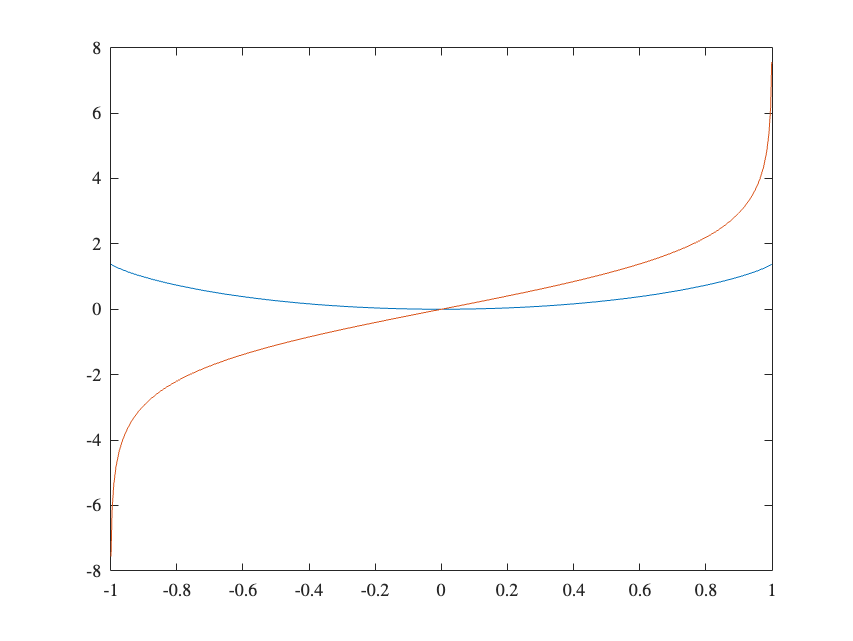

F  = @(s) (1+s) .* log(1+s) + (1-s) .* log(1-s);
dF = @(s) log(1+s) - log(1-s);
ddF = @(s) 2 ./ ( 1 - s.^2 );

plot(TimeLine.Pts.x,  F(TimeLine.Pts.x));    hold on
plot(TimeLine.Pts.x, dF(TimeLine.Pts.x));   hold off

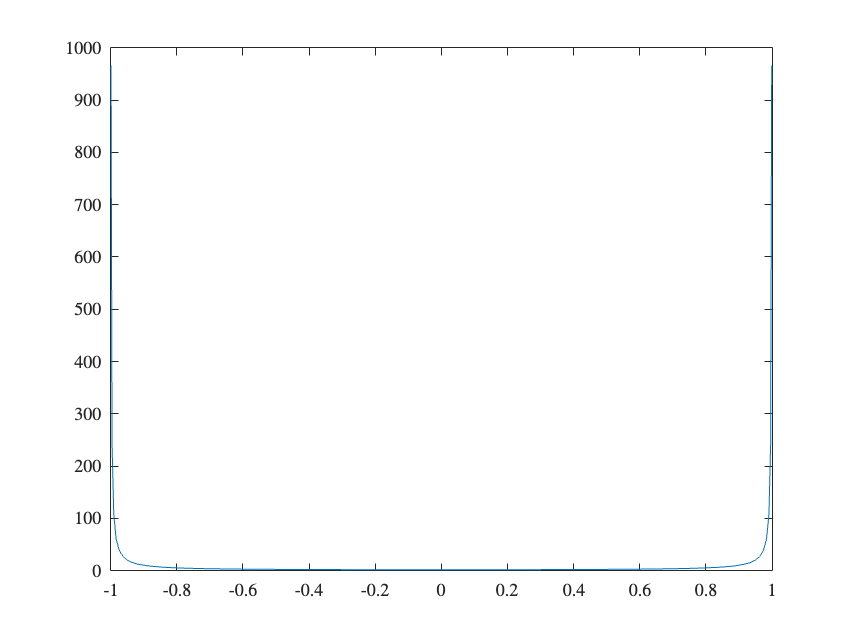

plot(TimeLine.Pts.x, ddF(TimeLine.Pts.x));   hold off

Now we can evaluate $\tilde{\mu} \left(x\right)$ and its Laplacian:

mu_tilde = dF(phi);    % Notice that time zero is not well defined
mu_tilde = mu_tilde - (Conv * phi' + Conv_D .* phi')';
g_tilde = g_tilde - (Lap_Space * mu_tilde')' ;

## Differential system

We aim to solve the following system:


$$\begin{array}{rcl}
\varphi_t - \Delta \mu &=& \tilde{g}
\\
\mu &=& F'(\varphi) - K\star \varphi
\\
\partial_n \mu &=& \partial_n \tilde{\mu}
\\
\varphi(x;0) &=& \varphi_0 
\end{array}$$


To do this we will use a differential equation solver and the following functions:

% The following two solvers might fail due to DAE
% Phi_t = NL_CH_Integrator_Source(phi_ic,  aBox, Diff, Ind,  Conv, Conv_D, dF, ddF, ...
%     mu_tilde, g_tilde, TimeLine );
% Phi_t = NL_CH_Integrator_Source_Simple(phi_ic,  aBox, Diff, Ind,  Conv, Conv_D, dF, ddF, ...
%     mu_tilde, g_tilde, TimeLine);
% DAE solver can be used to initialise the solution process or solve the
% system
Phi_t = NL_CH_Integrator_Source_DAE(phi_ic,  aBox, Diff, Ind,  Conv, Conv_D, TimeLine);

ans = 2.1502e-04

86 successful steps
25 failed attempts
1252 function evaluations
16 partial derivatives
44 LU decompositions
212 solutions of linear systems
Elapsed time is 0.212779 seconds.


ans = '5.81e-12'

We can check that energy has been preserved:

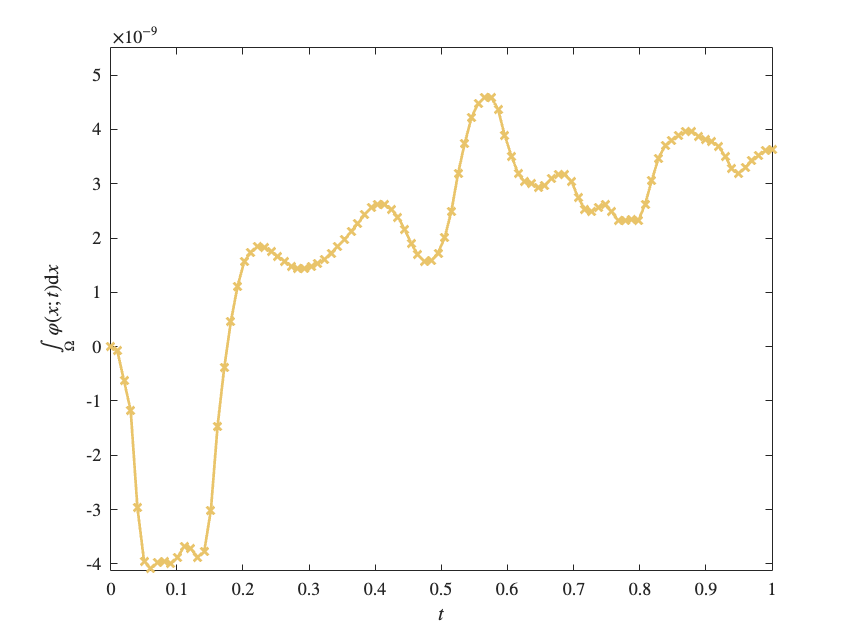

Time_Span_ODE = [0: outTimes(end)/99: outTimes(end)];

Mass_Time = Int * Phi_t';
figure(1)
plot(Time_Span_ODE, Mass_Time, 'LineWidth', 1.5, 'Color', ...
    '#e9c46a', 'LineStyle', '-', 'Marker','x')
ylim([min(Mass_Time)*1.01, max(Mass_Time)*1.2])

xlabel('$t$','Interpreter','latex'); 
ylabel( strcat(['$\int\limits_\Omega \varphi(x;t) ', ...
    '\mathrm{d}x $']), ...
    'Interpreter','latex');
set(gca, 'TickLabelInterpreter', 'latex');

% exportgraphics(figure(1), 'NLCH_Diffusion_Test_Mass.pdf', ...
%     'BackgroundColor','none', 'ContentType', 'vector', 'Resolution', 300)
hold off

Let us compute the error:

Phi_e = Phi_t * 0.0;

k = 1;
for t = Time_Span_ODE
    %IP_Time = TimeLine.ComputeInterpolationMatrixPhys(t).InterPol;
    if t == 0.0
        Phi_e(k,:) = phi_ic';
    else
        Phi_e(k,:) = exp(-t) * phi_ic'; %IP_Time * phi;
    end
    k = k + 1;
end

Now we can plot the solution:

%plots_in_box(Phi_t, aBox, Time_Span_ODE, Int)

The error:

%plots_in_box(Phi_e - Phi_t, aBox, Time_Span_ODE,  ...
% 'NLCH_Diffusion_Test_Error.gif', '$e(x;t)$')

And the evolution of the $\ell_2$ error in time:

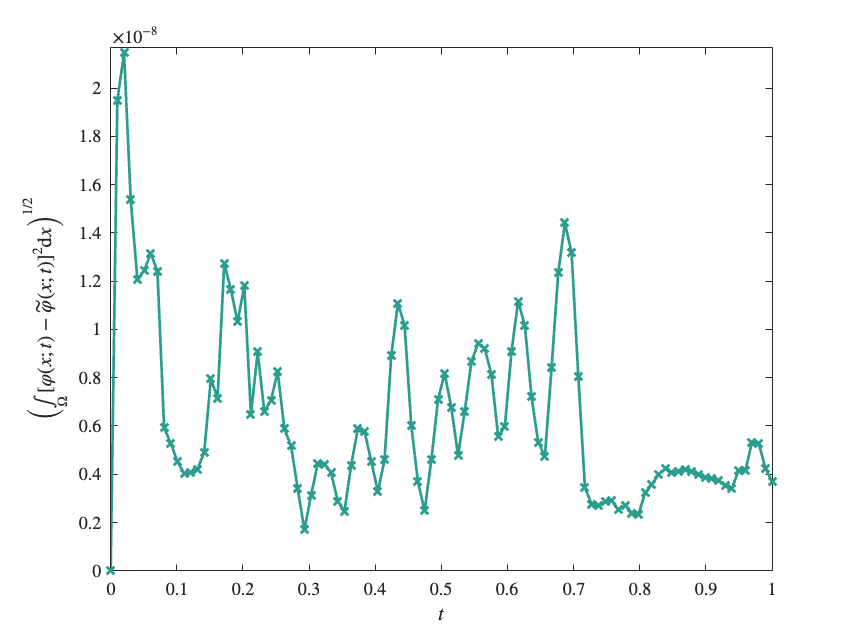

Err_Int = (Int * ((Phi_t - Phi_e)'.^2)).^0.5;

figure(3)
plot(Time_Span_ODE, Err_Int, 'LineWidth', 1.5, 'Color', ...
    '#2a9d8f', 'LineStyle', '-', 'Marker','x')
ylim([0,max(Err_Int)*1.01])

xlabel('$t$','Interpreter','latex'); 
ylabel( strcat(['$\left( \int\limits_\Omega [\varphi(x;t) ', ...
    '- \tilde{\varphi}(x;t)]^2 \mathrm{d}x \right)^{1/2} $']), ...
    'Interpreter','latex');

set(gca, 'TickLabelInterpreter', 'latex');


% exportgraphics(figure(3), 'NLCH_Diffusion_Test_Error_l2.pdf', ...
%     'BackgroundColor','none', 'ContentType', 'vector', 'Resolution', 300)